Simulated a focused Gaussian beam using the Optical Tweezers Toolbox

First we clear all existing variables and configure OTT warnings -- show warning only once and turn off warning related to future OTT function changes.

clear;
ott.warning('once');
ott.change_warnings('off');

Simulation parameters

n_medium = 1.0;         % Vacuum
wavelength0 = 1064e-9;  % Vacuum wavelength (m)

% Numerical aperture of the beam
% Assume a w0 = 15 um waist,
% the half opening angle is 
% lim_{z->\infty} arctan(w(z) / z),
% or `theta = lambda / (pi * w0 * n)` 
% in paraxial approx.
% where n = 1 is the index of the medium
% NA = n * sin(theta)
NA = 0.0226;

% Number of beam shape coefs to be used
Nmax = 200;

% Polarization in Jones vector. [ 1 0 ]: linear polarization in x
% [ 0 1 ]: y-polarized. [ 1 -i ] and [ 1 i ] are circularly polarized.
polarisation = [1 0];

% Spatial mode of the incident light in the Laguerre-Gauss
% basis. Fundamental Gaussian profile = [0 0].
lg_mode = [0 0];

beam_offset = [0; 0; 0];

Construct the beam

beam = ott.BscPmGauss('type','lg', 'mode', lg_mode, ...
                      'polarisation', polarisation, 'NA', NA,...
                      'offset', beam_offset, 'index_medium', n_medium, ...
                      'wavelength0', wavelength0, ...
                      'Nmax', Nmax);

Unrecognized function or variable 'lg_mode'.


% Normalize the beam power before moving forward
beam.power = 1.0;

beam_angle = asin(NA/n_medium)*180/pi;
w0 = lg_mode_w0( lg_mode, beam_angle );

% Create the trapping field:
% Use this for focused Gaussian field
[n,m,a0,b0] = bsc_pointmatch_farfield(Nmax,1,[ lg_mode w0 1 polarisation 90 beam_offset ]);

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

[a,b,n,m] = make_beam_vector(a0,b0,n,m);

% Normalize total power of wave sum to 1.
pwr = sqrt(sum( abs(a).^2 + abs(b).^2 ));
a=a/pwr;
b=b/pwr;
mybeam = ott.Bsc(a,b,'regular','incident');

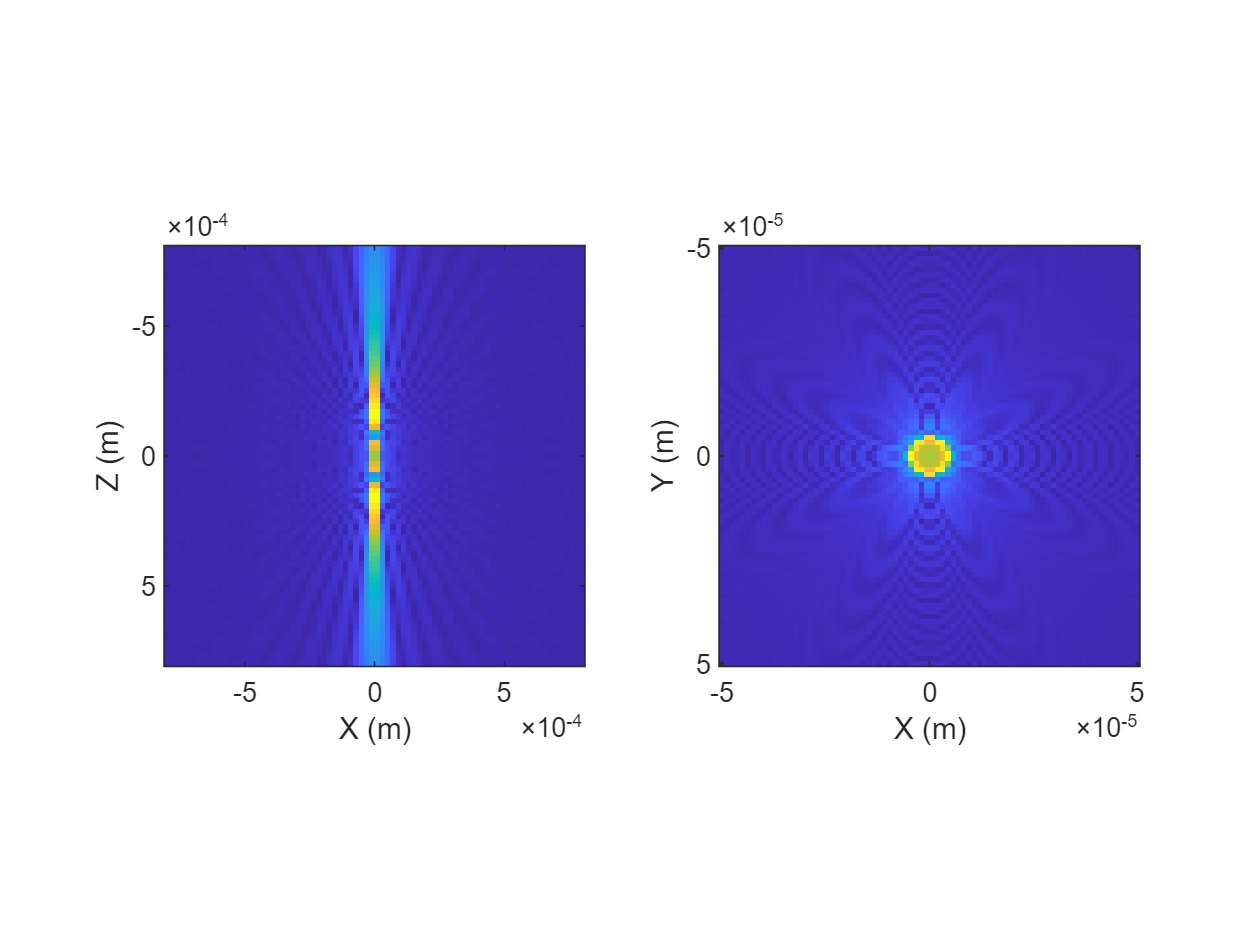

beam.Nmax = 100;
% Near field
% Vector spherical wave function might not be a good approximation
% for the x-z shape (Rayleigh range = 6.64e-4 m)
figure();
beam.basis = 'regular';
subplot(1, 2, 1);
beam.visualise('axis', {[1 0 0], [0 0 1]}, 'range', [8e-4 8e-4]);
xlabel('X (m)');
ylabel('Z (m)');
beam.basis = 'regular';
radius = 5e-6;
subplot(1, 2, 2);
beam.visualise('axis', 'z', 'range', [5e-5 5e-5]); %, 'mask', @(xyz) vecnorm(xyz) < radius);
xlabel('X (m)')
ylabel('Y (m)')

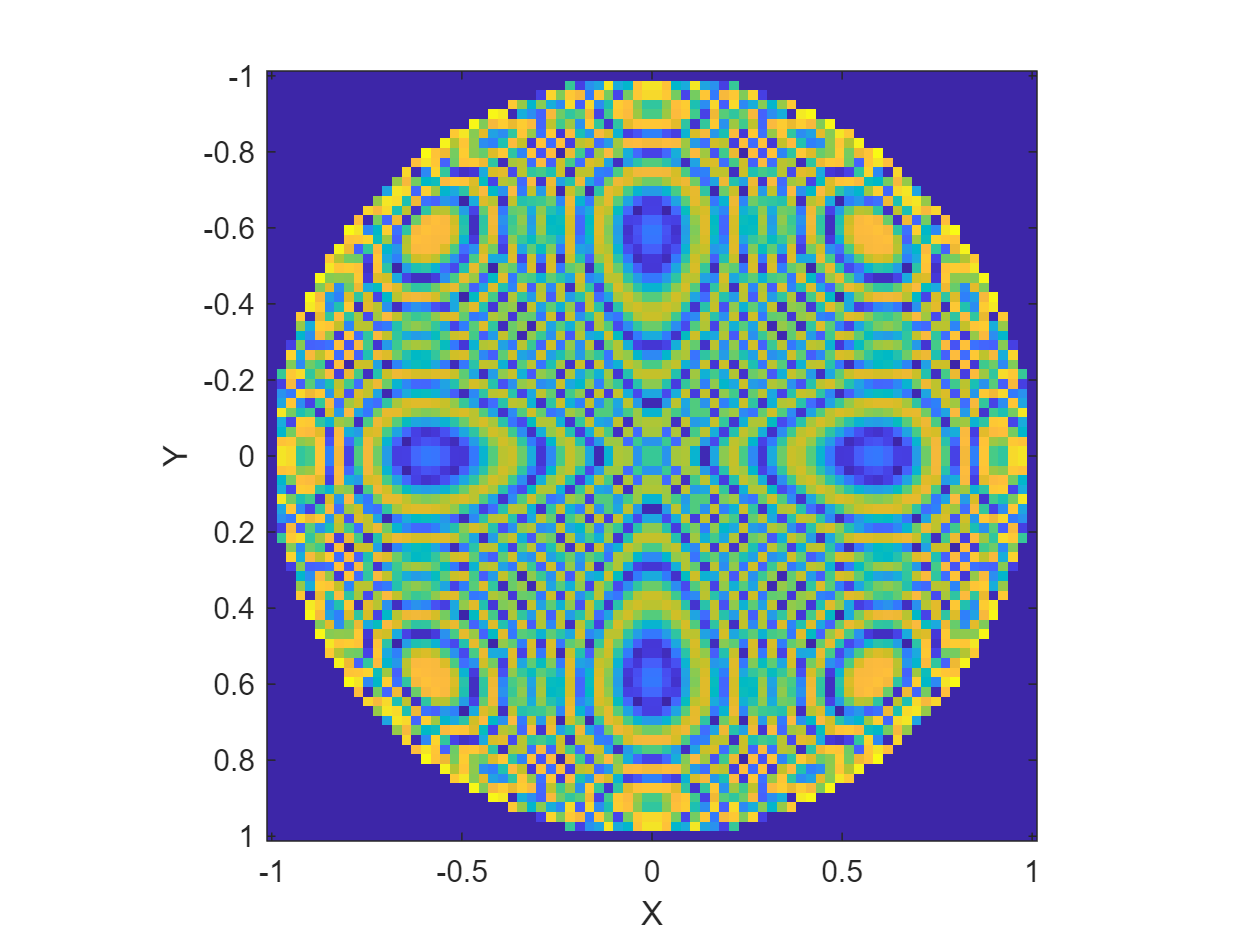

% Far field visualization
beam.basis = 'incoming';

figure();
beam.visualiseFarfield('dir', 'pos');

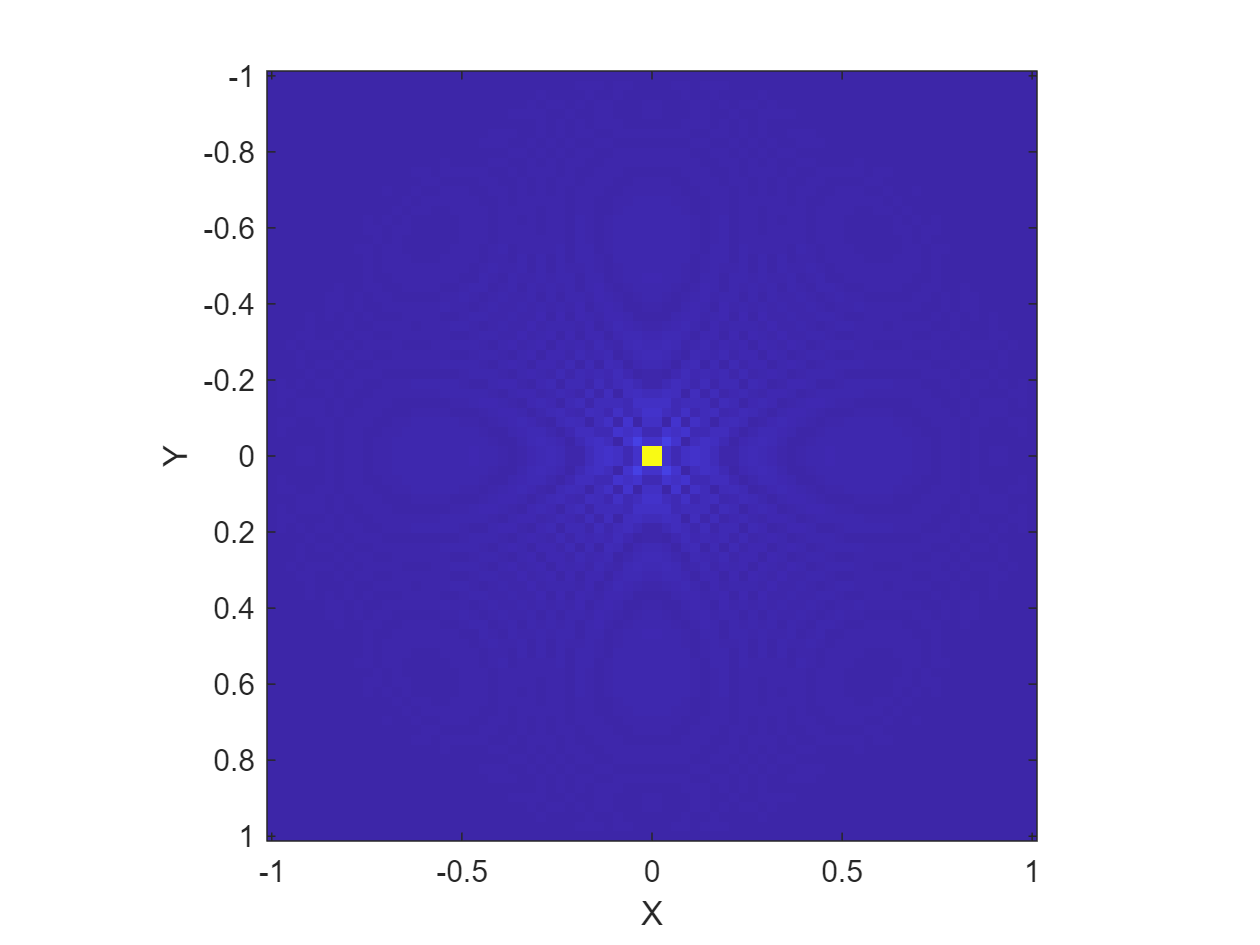

figure();
beam.visualiseFarfield('dir', 'neg');

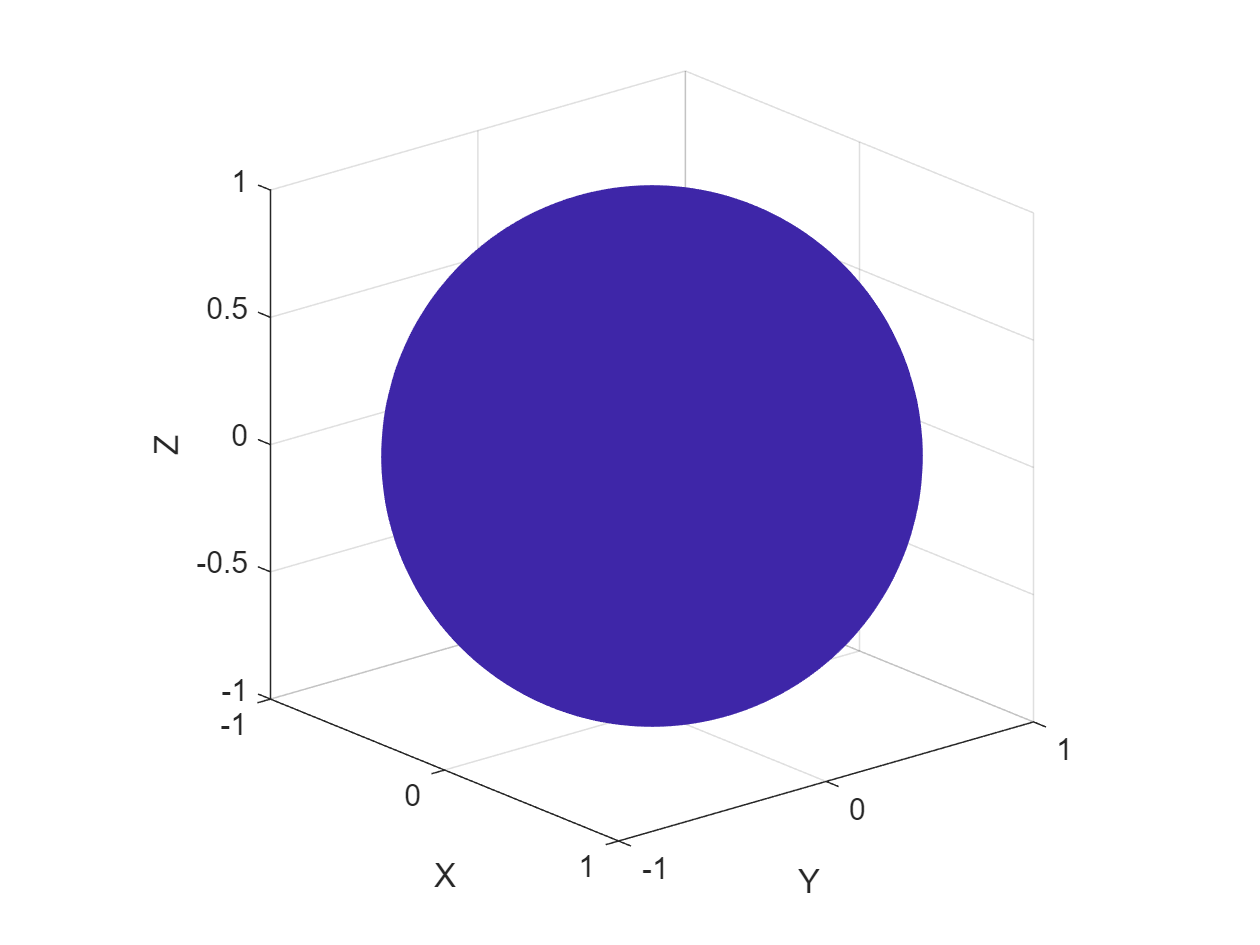

figure();
beam.visualiseFarfieldSphere('type', 'sphere');

Calculate the T-matrix

n_particle = 1.5;
radius = 5e-6;
T = ott.Tmatrix.simple('sphere', radius, 'wavelength0', wavelength0, ...
   'index_medium', n_medium, 'index_particle', n_particle, 'Nmax', Nmax);

T

T =   TmatrixMie with properties:

         radius: 5.0000e-06
       k_medium: 5.9052e+06
     k_particle: 8.8579e+06
    mu_relative: 1
           data: [20400×20400 double]
           Nmax: [100 100]
           type: 'scattered'


sbeam = T * beam;

sbeam

sbeam =   BscPmGauss with properties:

                     gtype: 'lg'
                      mode: [0 0]
              polarisation: [1 0]
          truncation_angle: 1.5708
                    offset: [3×1 double]
                     angle: 0.0226
        translation_method: 'Default'
           angular_scaling: 'tantheta'
    inv_coefficient_matrix: []
                         a: [10200×1 double]
                         b: [10200×1 double]
                  k_medium: 5.9052e+06
                        dz: 0
                     basis: 'outgoing'
                      type: 'scattered'
                     omega: 6.2832
                      Nmax: 100
                     power: 0.0981
                    Nbeams: 1
                wavelength: 1.0640e-06
                     speed: 1.0640e-06


Scattered and total field around the beam focus

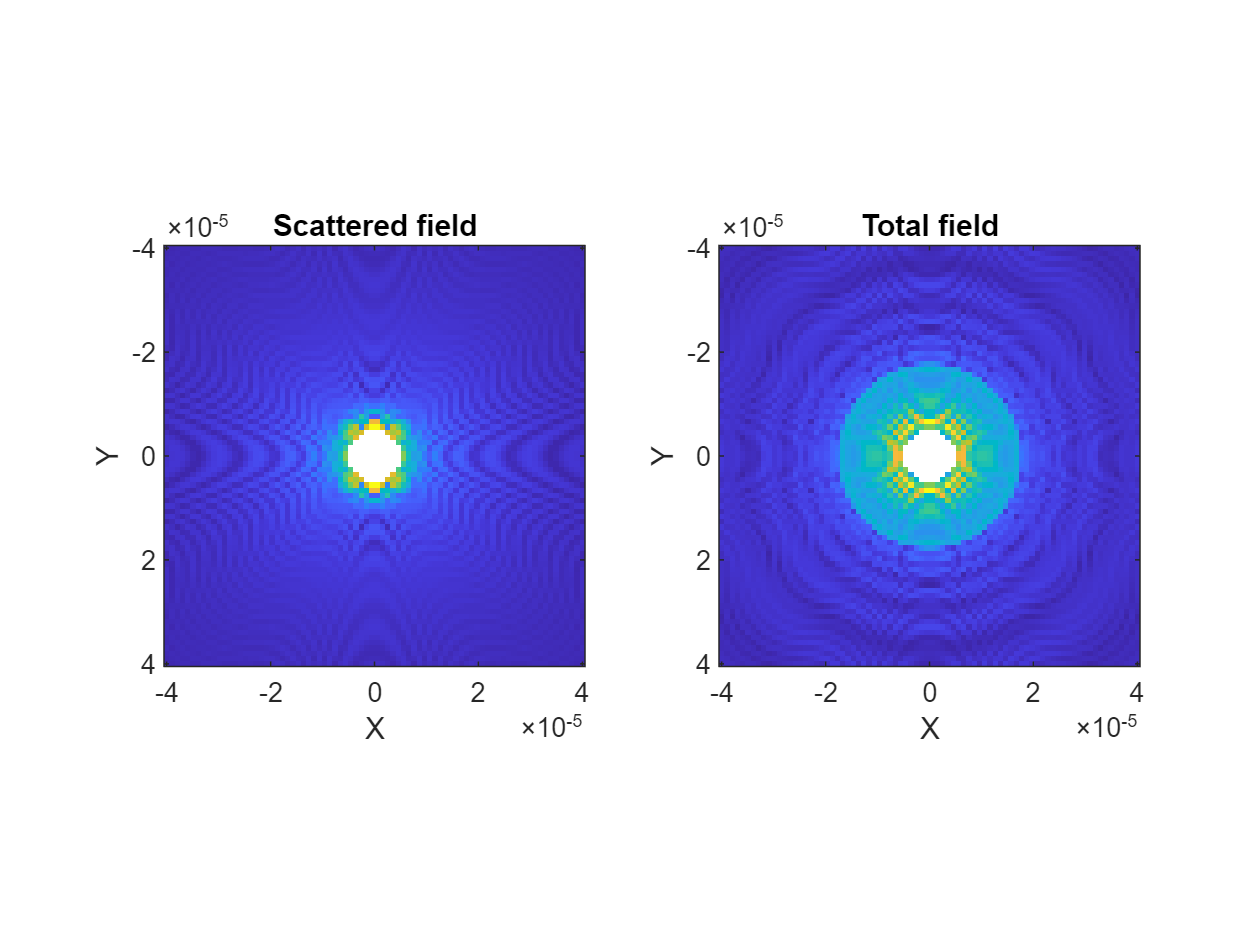

figure();
subplot(1, 2, 1);
sbeam.basis = 'regular';
sbeam.visualise('axis', 'z', 'field', 'irradiance',...
   'mask', @(xyz) vecnorm(xyz) < radius, 'range', [20,20]*2e-6)
title('Scattered field');

subplot(1, 2, 2);
tbeam = sbeam.totalField(beam);
tbeam.basis = 'regular';
tbeam.visualise('axis', 'z', 'field', 'irradiance',...
   'mask', @(xyz) vecnorm(xyz) < radius, 'range', [20,20]*2e-6)
title('Total field');

tbeam

tbeam =   BscPmGauss with properties:

                     gtype: 'lg'
                      mode: [0 0]
              polarisation: [1 0]
          truncation_angle: 1.5708
                    offset: [3×1 double]
                     angle: 0.0226
        translation_method: 'Default'
           angular_scaling: 'tantheta'
    inv_coefficient_matrix: []
                         a: [10200×1 double]
                         b: [10200×1 double]
                  k_medium: 5.9052e+06
                        dz: 0
                     basis: 'regular'
                      type: 'total'
                     omega: 6.2832
                      Nmax: 100
                     power: 1.0000
                    Nbeams: 1
                wavelength: 1.0640e-06
                     speed: 1.0640e-06


Far-field pattern of the total beam

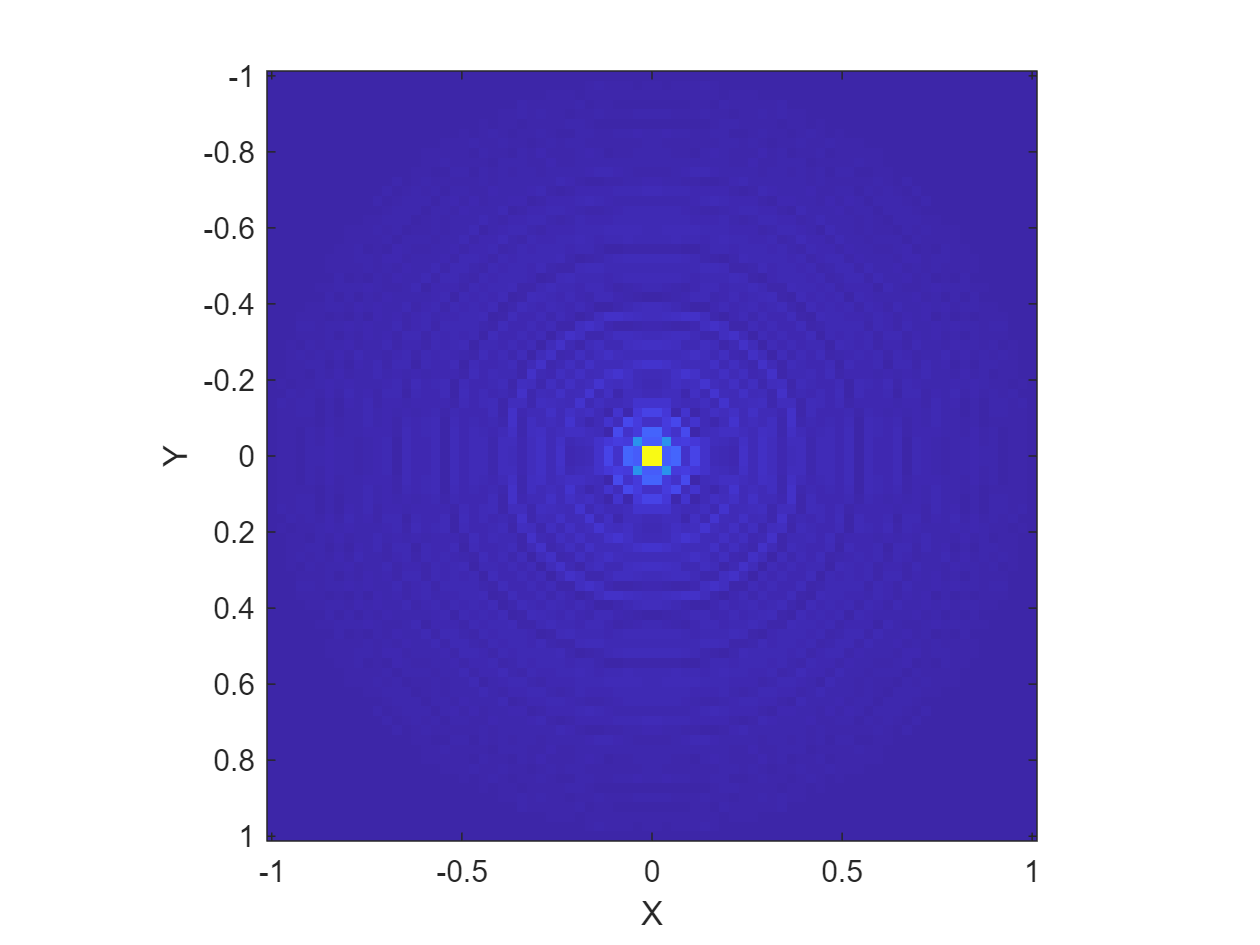

tbeam.basis = 'incoming';

figure();
tbeam.visualiseFarfield('dir', 'neg');

beam.set_Nmax(250);
beam.basis = 'incoming';

figure();
beam.visualiseFarfield('dir', [0 0]);


% Calculate the force along z
wavelength_medium = wavelength0/n_medium;
z = [0;0;1] * linspace(-30, 30, 100) * wavelength_medium;
fz = ott.forcetorque(beam, T, 'position', z);

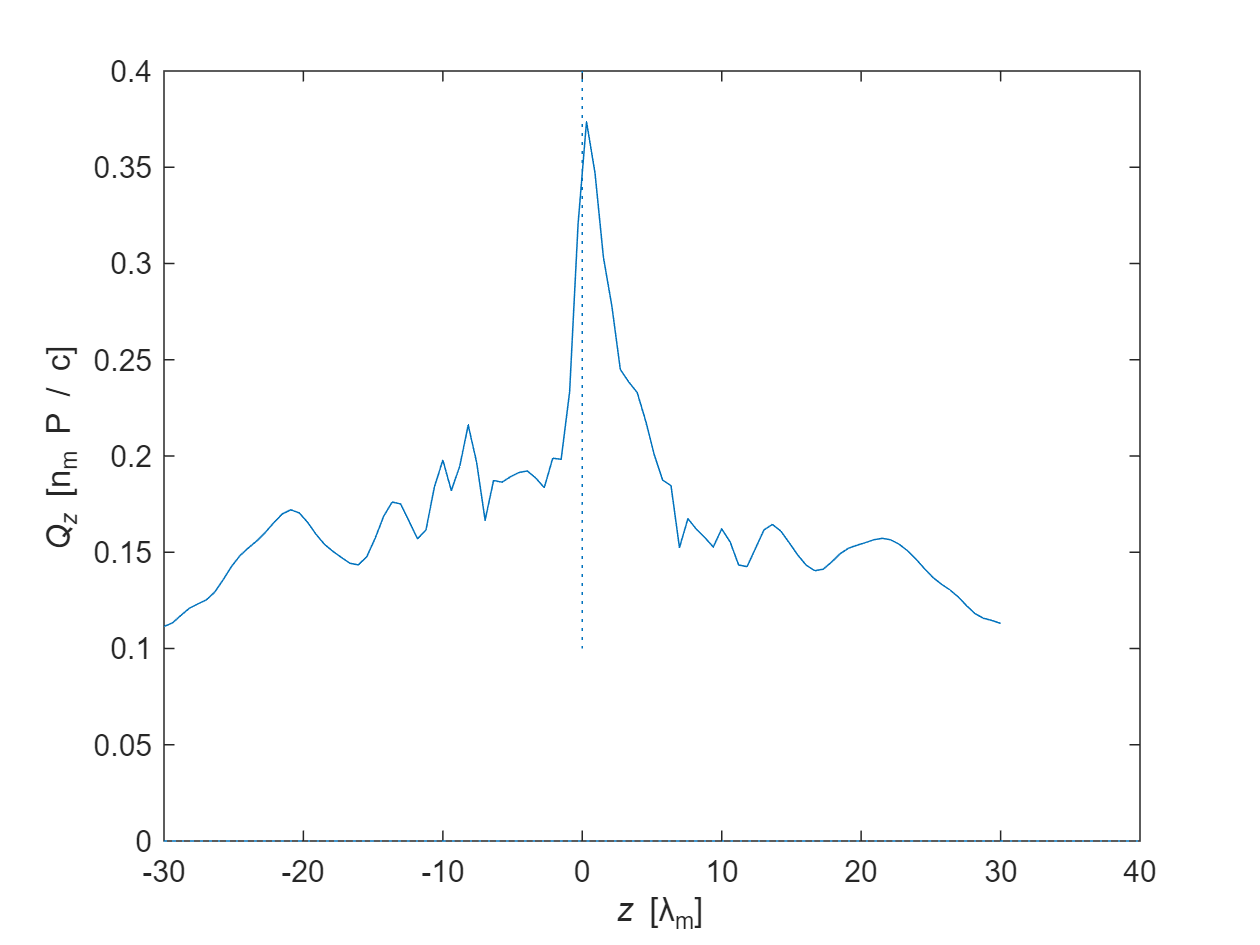

% Generate a plot
figure();
plot(z(3, :)/wavelength_medium,fz(3, :));
xlabel('{\it z} [\lambda_m]');
ylabel('{\it Q_z} [n_m P / c]');
aa = axis;
hold on;
line(aa(1:2),[ 0 0 ],'linestyle',':');
line([0 0],aa(3:4),'linestyle',':');
hold off;